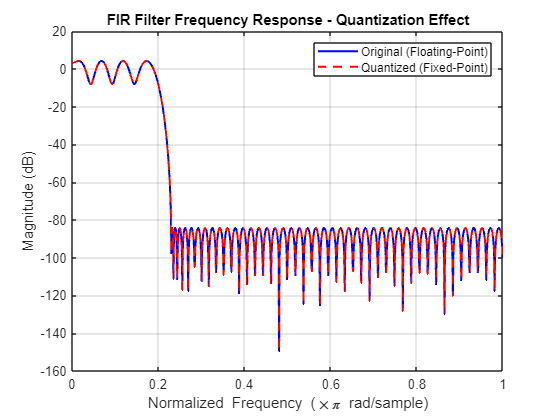

% FIR Filter Design and Export to SystemVerilog
clc; clear;

% Filter Specifications
N = 102; % Number of filter taps
Fpass = 0.2;
Fstop = 0.23;
W = [1 10^(80/20)]; % Weighting for stopband attenuation

% Design FIR filter (Parks-McClellan algorithm)
h = firpm(N-1, [0 Fpass Fstop 1], [1 1 0 0], W);

% Scale and Quantize Coefficients (Fixed-point 32-bit)
h_fixed = round(h * 2^31); % Convert to Q15 fixed-point format
h_fixed = max(min(h_fixed, 2^31), -2^31); % Saturate to 32-bit range

% Frequency Response Comparison
[H, w] = freqz(h, 1, 1024);  % Floating-point filter
[Hq, wq] = freqz(h_fixed / 2^31, 1, 1024); % Quantized filter

% Plot Frequency Response
figure;
plot(w/pi, 20*log10(abs(H)), 'b', 'LineWidth', 1.5); hold on;
plot(wq/pi, 20*log10(abs(Hq)), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('Original (Floating-Point)', 'Quantized (Fixed-Point)');
title('FIR Filter Frequency Response - Quantization Effect');



% === Save Floating-Point Coefficients ===
float_file = fullfile('fir_coeffs_float.mem');
fid = fopen(float_file, 'w');
for i = 1:N
    fprintf(fid, '%.10f\n', h(i)); % Save as floating-point values
end
fclose(fid);
disp(['Floating-point coefficients saved to: ', float_file]);

Floating-point coefficients saved to: fir_coeffs_float.mem



% === Save Fixed-Point (Quantized) Coefficients ===
fixed_file = fullfile('fir_coeffs_fixed.mem');
fid = fopen(fixed_file, 'w');
for i = 1:N
    fprintf(fid, '%d\n', h_fixed(i)); % Save as integers (Q15 format)
end
fclose(fid);
disp(['Fixed-point coefficients saved to: ', fixed_file]);

Fixed-point coefficients saved to: fir_coeffs_fixed.mem



% === Save Fixed-Point Coefficients in Hexadecimal Format ===
hex_file = fullfile('fir_coeffs_hex.mem');
fid = fopen(hex_file, 'w');
for i = 1:N
    % Convert to 16-bit signed hexadecimal (4 characters)
    hex_value = dec2hex(typecast(int16(h_fixed(i)), 'uint16'), 4);
    fprintf(fid, '%s\n', hex_value); % Save as hexadecimal values
end
fclose(fid);
disp(['Fixed-point coefficients (hex) saved to: ', hex_file]);

Fixed-point coefficients (hex) saved to: fir_coeffs_hex.mem



% === Save Fixed-Point Coefficients in Binary Format ===
binary_file = fullfile('fir_coeffs_binary.mem');
fid = fopen(binary_file, 'w');
for i = 1:N
    % Convert to 16-bit signed binary (16 characters)
    binary_value = dec2bin(typecast(int16(h_fixed(i)), 'uint16'), 16);
    fprintf(fid, '%s\n', binary_value); % Save as binary values
end
fclose(fid);
disp(['Fixed-point coefficients (binary) saved to: ', binary_file]);

Fixed-point coefficients (binary) saved to: fir_coeffs_binary.mem
